Experiment 3

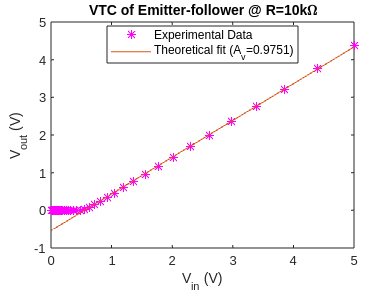

clear
load("data/exp3.mat");
figure();
plot(exp3_v_in,exp3_v_out,"m*","DisplayName","Experimental Data")
hold on
title("VTC of Emitter-follower @ R=10k\Omega")
xlabel("V_{in} (V)");
ylabel("V_{out} (V)");
legend("Location","best")
[f2, l2, m2, b2, n2] = linefit(exp3_v_in, exp3_v_out,5e-4);
fitline2 = m2 * exp3_v_in + b2;
plot(exp3_v_in,fitline2,'DisplayName', 'Theoretical fit (A_{v}=0.9751)');
hold off

Difference between V_in and V_out is the base emitter voltage drop V_be. This is affected by the collector current I_c (as emitter current I_e is approximately equal to I_c).

Experiment 4

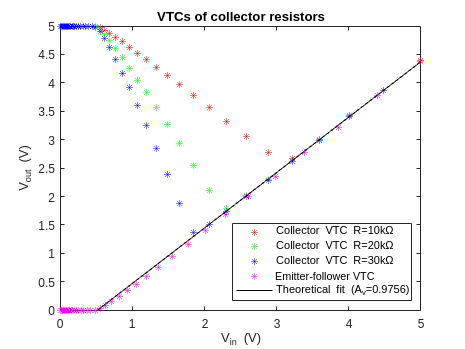


load("data/exp4.mat");
figure();
plot(exp4_v_in_10k,exp4_v_out_10k,"r*","DisplayName","Collector VTC R=10k\Omega")
hold on
plot(exp4_v_in_20k,exp4_v_out_20k,"g*","DisplayName","Collector VTC R=20k\Omega")
plot(exp4_v_in_30k,exp4_v_out_30k,"b*","DisplayName","Collector VTC R=30k\Omega")
plot(exp3_v_in,exp3_v_out,"m*","DisplayName","Emitter-follower VTC")
title("VTCs of collector resistors")
legend("Location","southeast")
xlabel("V_{in} (V)");
ylabel("V_{out} (V)");
ylim([-0.0030 5]);
%combine data to add theoretical fit
idx_10k = exp4_v_in_10k > 3.21;
filtered_v_in_10k = exp4_v_in_10k(idx_10k);
filtered_v_out_10k = exp4_v_out_10k(idx_10k);
idx_20k = exp4_v_in_20k > 2.3;
filtered_v_in_20k = exp4_v_in_20k(idx_20k);
filtered_v_out_20k = exp4_v_out_20k(idx_20k);
idx_30k = exp4_v_in_30k > 1.85;
filtered_v_in_30k = exp4_v_in_30k(idx_30k);
filtered_v_out_30k = exp4_v_out_30k(idx_30k);
new_x = double([filtered_v_in_10k filtered_v_in_20k filtered_v_in_30k exp3_v_in]);
new_y = double([filtered_v_out_10k filtered_v_out_20k filtered_v_out_30k exp3_v_out]);

%add fit
[f1, l1, m1, b1, n1] = linefit(new_x, new_y,5e-4);
fitline1 = m1 * new_x + b1;
plot(new_x,fitline1,"black",'DisplayName', 'Theoretical fit (A_{v}=0.9756)');

Emitter current I_e affects this, inversely proportional to r_e which is inversely proportional to voltage gain. Degeneration resistor also significantly affects this, as does the current gain beta.